load ifk.mat

[m,n] = size(d);
a = 0; b = 1;

n = m;

sig  = 1e-4;

dx = (b-a)/m;
g = @(x,y) x*exp(-x*y);

x = [];
for j = 1:n
    x = [x  a + (dx/2) + (j-1)*dx]; %form x
end
y = x;

G = zeros(m,n);

for i = 1:m
    for j = 1:n
        G(i,j) = g(x(j),y(i)).*dx; %form G
    end
end

% Get the singular values for the system matrix
[U,S,V] = svd(G);

Si = diag(S);

i = 4;
mdagger = 0;
for j = 1:i
    mdagger = mdagger + (U(:,j)'*d/Si(j))*V(:,j);
end
mdagger;

Sii = Si(1:i-1);
mest = 0;
for j = 1:i-1
    mest = mest + (U(:,j)'*d/Sii(j))*V(:,j);
end
mest;

%true model
mtrue = @(x) exp(-10*(x-0.2).^2) + 0.4*exp(-10*(x-0.9).^2);

mtrue(x);

### N0.1

chi = @(m) (norm(d - G*m,2)^2)/sig^2; %function Chi-square obs

chi_tsvd_i = chi(mdagger) %TSVD_i

chi_tsvd_i = 0.9433

chi_tsvd_i_1 = chi(mest) %TSVD_i-1

chi_tsvd_i_1 = 0.9437

chi_mtrue = chi(mtrue(x)') %true estimates

chi_mtrue = 22.4482

expected_value = m-n

expected_value = 0

### Discuss the values you calculated in relationship to each other, and to the expected value.

The $\chi^{2}$ for the TSVD parameter estimates is almost the same and way too small compared to that of the true estimates which is 22.4482. However, the $\chi^{2}$ for the TSVD  near to the expected value, $\nu = 0$ compared to that of the true estimates. This means that the true parameter estimates  don't follow a chi-square distribution. 

### N0.2

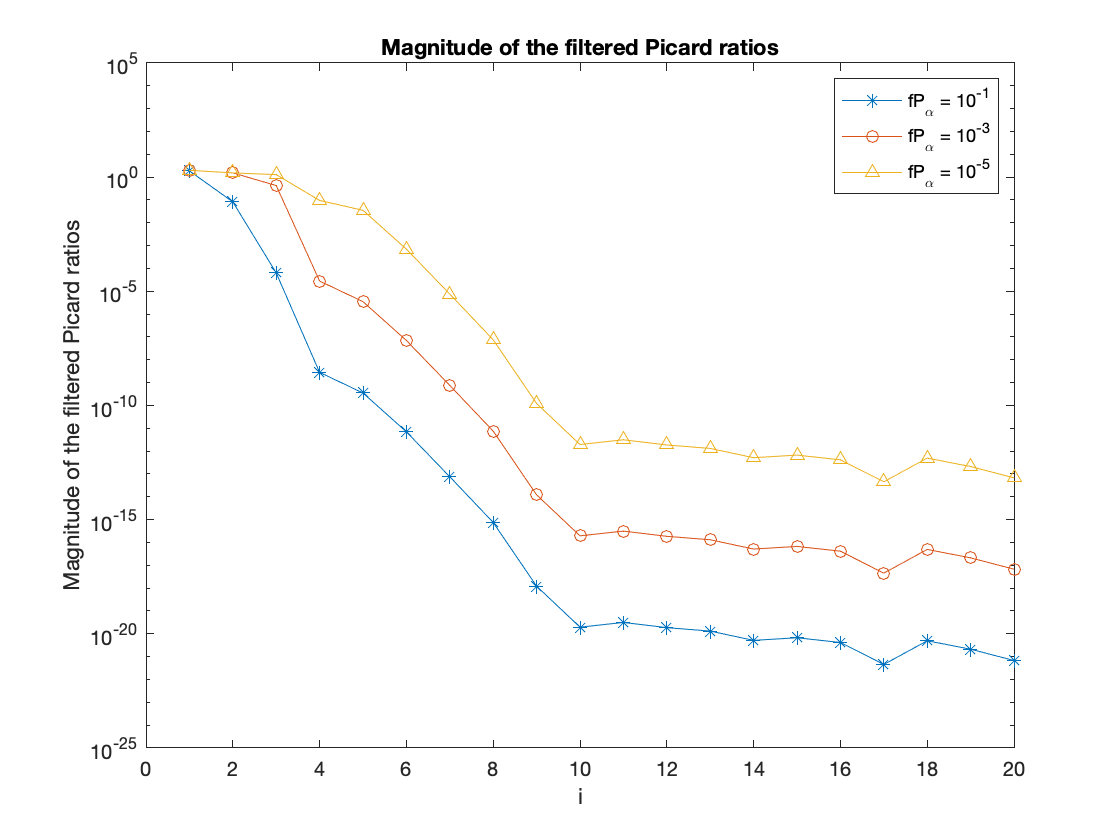

alpha = [1e-1 1e-3 1e-5];
fp = [];
for i = 1:3
    fp= [fp filtered(alpha(i),Si,U,d,m)];
end

figure(1)
semilogy(fp(1:20),'-*'); hold on
semilogy(fp(21:40),'-o'); hold on
semilogy(fp(41:60),'-^')
legend('fP_{\alpha} = 10^{-1}','fP_{\alpha} = 10^{-3}','fP_{\alpha} = 10^{-5}')
xlabel('i'); ylabel('Magnitude of the filtered Picard ratios')
title('Magnitude of the filtered Picard ratios')

### Discuss how they compare to the unfiltered Picard ratios in the Ch3: Discrete ill-posed problems individual activity.

As seen form the graph below, they filtered and unfiltered all start at the same point, however, after $i=4$, the unfiltered one increases rapidly  up to $i=10$, and then somehow tends to flatten,  while the filtered ones, decreases in the same sense depending for the value of $\alpha$.

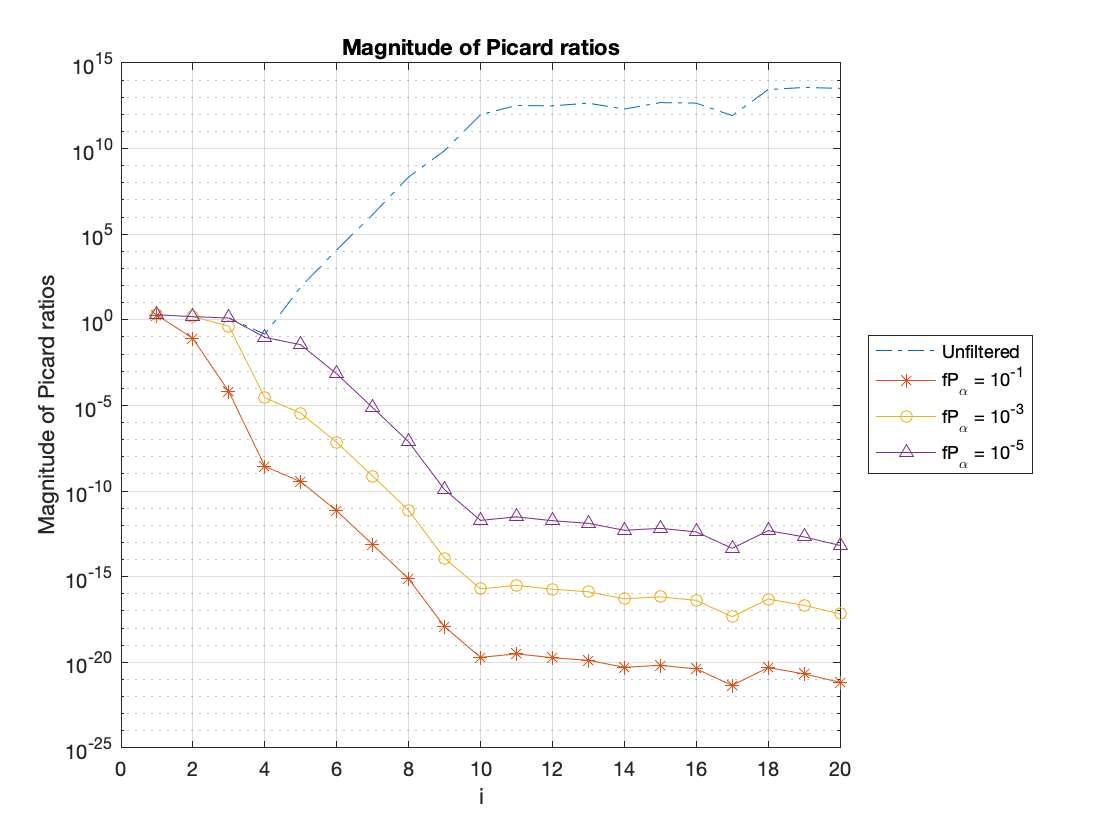

Picard = [];
for i = 1:m
    Picard = [Picard abs((U(:,i)'*d)/Si(i))];
end

figure(3)
semilogy(Picard,'-.'); hold on
semilogy(fp(1:20),'-*'); hold on
semilogy(fp(21:40),'-o'); hold on
semilogy(fp(41:60),'-^'); grid on
legend('Unfiltered','fP_{\alpha} = 10^{-1}','fP_{\alpha} = 10^{-3}','fP_{\alpha} = 10^{-5}','Location','eastoutside')
ylabel('Magnitude of Picard ratios'); xlabel('i');
title('Magnitude of Picard ratios');

### N0.3 Plot the estimates for each value of α on the same graph.

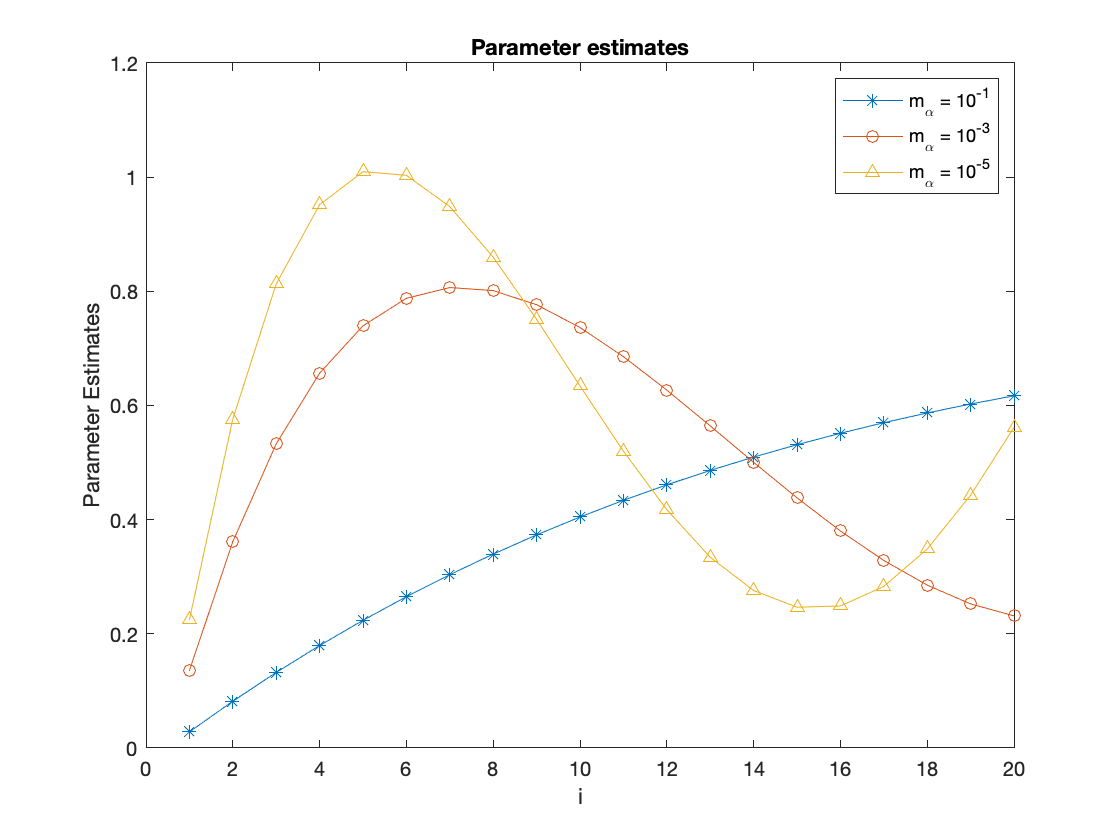

m = @(alpha) (G'*G + (alpha^2)*eye(m))\(G'*d);
m1 = m(alpha(1));
m2 = m(alpha(2));
m3 = m(alpha(3));

figure(2)
plot(m1,'-*'); hold on
plot(m2,'-o'); hold on
plot(m3,'-^')
legend('m_{\alpha} = 10^{-1}','m_{\alpha} = 10^{-3}','m_{\alpha} = 10^{-5}')
xlabel('i'); ylabel('Parameter Estimates')
title('Parameter estimates')

### Discuss the accuracy of the model parameter estimates with different values of α, and relate them to the Picard ratios in 2.

Based on the graph below, comparing the model parameter estimates at different values of alpha to the true model, tells us that the smaller the alpha the more close the estimates are to the true estimates, and the bigger the alpha, the further the estimates are ,a way form the true estimates, which means the more we increase alpha, we are over smoothening the data. This is also well exhibited in the Picard ratio plot in figure(3), as alpha increase, the more the graph diverges away from the true solution. 

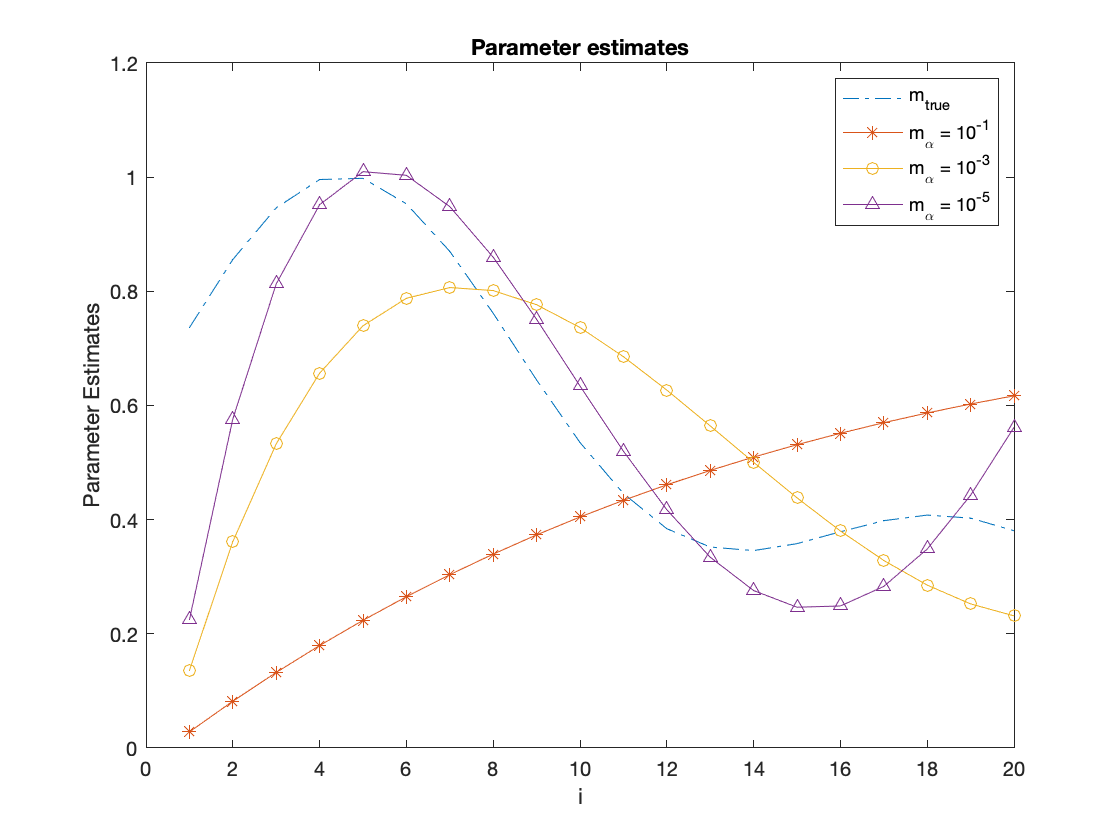

figure(4)
plot(mtrue(x)','-.'); hold on
plot(m1,'-*'); hold on
plot(m2,'-o'); hold on
plot(m3,'-^')
legend('m_{true}','m_{\alpha} = 10^{-1}','m_{\alpha} = 10^{-3}','m_{\alpha} = 10^{-5}')
xlabel('i'); ylabel('Parameter Estimates')
title('Parameter estimates')

### Report the $\chi_{obs}^{2}$ values for each value of $\alpha$.

residual_a1 = chi(m1) % for alpha = 1e-1

residual_a1 = 3.2498e+05

residual_a2 = chi(m2) % for alpha = 1e-3

residual_a2 = 38.4176

residual_a3 = chi(m3)  %for alpha = 1e-5

residual_a3 = 0.9433

### Compare them to the values you found in 1.

The $\chi_{obs}^{2}$ for the different values of alpha, are far away from the expected value 0, except for  $\alpha$ = $10^{-5}$ which means that the data follows a $\chi^{2}$ distribution for only   $\alpha$ = $10^{-5}$ and is equivalent to the $\chi_{obs}^{2}$ obtained for TSVD parameter at $i=4$

function [fp] = filtered(alpha,Si,U,d,m)
    fp = [];
    for i = 1:m
        fi = (Si(i)^2)/(Si(i)^2 + alpha^2);
        fp = [fp abs(fi*U(:,i)'*d/Si(i))];
    end
end